clear
figItterator = 1;


input = [0:10:350];
normalizedInput = (input - 180) / 180;

x = [-5:0.1:5];

%Sigmoid

figure(figItterator)

subplot(3,3,1);
activation = 20 ./ (1 + exp(-1*normalizedInput))+20;
plot(normalizedInput, activation)
title("Sigmoid, exp -1")
ylabel("Motor speed")
xlabel("Angle - Normalized")

subplot(3,3,2);
activation = 20 ./ (1 + exp(-5*normalizedInput))+20;
plot(normalizedInput, activation)
title("Sigmoid, exp -5")
ylabel("Motor speed")
xlabel("Angle - Normalized")

subplot(3,3,3);
activation = 20 ./ (1 + exp(-10*normalizedInput))+20;
plot(normalizedInput, activation)
title("Sigmoid, exp -10")
ylabel("Motor speed")
xlabel("Angle - Normalized")

subplot(3,3,4);
activation = 20 ./ (1 + exp(-15*normalizedInput))+20;
plot(normalizedInput, activation)
title("Sigmoid, exp -15")
ylabel("Motor speed")
xlabel("Angle - Normalized")

subplot(3,3,5);
activation = 20 ./ (1 + exp(-20*normalizedInput))+20;
plot(normalizedInput, activation)
title("Sigmoid, exp -20")
ylabel("Motor speed")
xlabel("Angle - Normalized")

subplot(3,3,6);
activation = 20 ./ (1 + exp(-25*normalizedInput))+20;
plot(normalizedInput, activation)
title("Sigmoid, exp -25")
ylabel("Motor speed")
xlabel("Angle - Normalized")

subplot(3,3,8);
activation = 20 ./ (1 + exp(-30*normalizedInput))+20;
plot(normalizedInput, activation)
title("Sigmoid, exp -30")
ylabel("Motor speed")
xlabel("Angle - Normalized")

figItterator = figItterator +1;
figure(figItterator)


activation = 20 ./ (1 + exp(-1*normalizedInput))+20;
plot(normalizedInput, activation)
title("Sigmoid, exp -1")
ylabel("Motor speed")
xlabel("Angle - Normalized")
hold on

activation = 20 ./ (1 + exp(-5*normalizedInput))+20;
plot(normalizedInput, activation)
title("Sigmoid, exp -5")
ylabel("Motor speed")
xlabel("Angle - Normalized")
hold on

activation = 20 ./ (1 + exp(-10*normalizedInput))+20;
plot(normalizedInput, activation)
title("Sigmoid, exp -10")
ylabel("Motor speed")
xlabel("Angle - Normalized")
hold on

activation = 20 ./ (1 + exp(-15*normalizedInput))+20;
plot(normalizedInput, activation)
title("Sigmoid, exp -15")
ylabel("Motor speed")
xlabel("Angle - Normalized")
hold on

activation = 20 ./ (1 + exp(-20*normalizedInput))+20;
plot(normalizedInput, activation)
title("Sigmoid, exp -20")
ylabel("Motor speed")
xlabel("Angle - Normalized")
hold on

activation = 20 ./ (1 + exp(-25*normalizedInput))+20;
plot(normalizedInput, activation)
title("Sigmoid, exp -25")
ylabel("Motor speed")
xlabel("Angle - Normalized")
hold on

activation = 20 ./ (1 + exp(-30*normalizedInput))+20;
plot(normalizedInput, activation)
title("All Sigmoid exponential constant")
ylabel("Motor speed")
xlabel("Angle - Normalized")
legend("e^{-1}","e^{-5}","e^{-10}","e^{-15}","e^{-20}","e^{-25}","e^{-30}",'Location',"southeast")
hold off

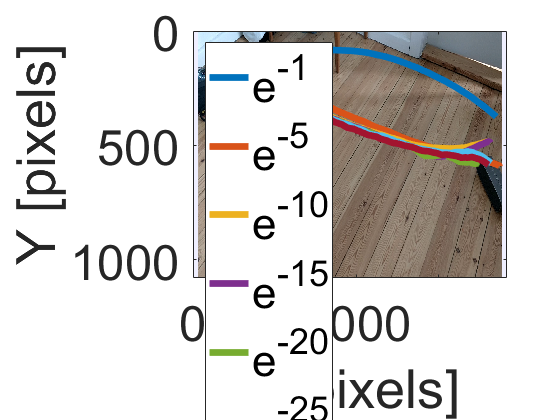

clear

figItterator = 10;

min_x = 0;
max_x = 1920;
min_y = 0;
max_y = 1080;


%x = x + 50; %Offset to match the video with footage
img = imread("test02opstilling.png");

figure(figItterator)
set(gca,'FontSize',37)
imagesc([min_x max_x], [min_y max_y], img);
hold on
data = csvread('exp1Tracker.csv');
x = data(:, 1);
y = data(: , 2);
p=plot(y(1:444),x(1:444));
p.LineWidth = 5;
xlabel("X [pixels]")
ylabel("Y [pixels]")
hold on
data = csvread('exp5Tracker.csv');
x = data(:, 1);

y = data(: , 2);
p=plot(y(1:408),x(1:408));
p.LineWidth = 5;
hold on 
data = csvread('exp10Tracker.csv');
x = data(:, 1);

y = data(: , 2);
p=plot(y(1:380),x(1:380));
hold on
p.LineWidth = 5;
data = csvread('exp15Tracker.csv');
x = data(:, 1);
y = data(: , 2);
p=plot(y,x);
p.LineWidth = 5;
hold on

p.LineWidth = 5;
data = csvread('exp20Tracker.csv');
x = data(:, 1);
y = data(: , 2);
p=plot(y(1:450),x(1:450));
p.LineWidth = 5;
hold on

data = csvread('exp25Tracker.csv');
x = data(:, 1);
y = data(: , 2);
p=plot(y(1:366),x(1:366));
p.LineWidth = 5;
hold on

data = csvread('exp30Tracker.csv');
x = data(:, 1);
y = data(: , 2);
p=plot(y(1:363),x(1:363));
p.LineWidth = 5;
hold on
legend("e^{-1}","e^{-5}","e^{-10}","e^{-15}","e^{-20}","e^{-25}","e^{-30}",'Location',"southwest")